A = [1.1269 -0.4940 0.1129
     1.0000       0      0
          0  1.0000      0];

B = [-0.3832
      0.5919
      0.5191];

C = [1 0 0];

D = 0;

Ts = -1;
sys = ss(A, [B B], C, D, Ts, 'InputName', {'u' 'w'},'OutputName', 'y');

Q = 2.3;
R = 1;

% Use the kalman command to design the filter.
[kalmf, L, ~, Mx, Z] = kalman(sys, Q, R);

kalmf = kalmf(1, :);

% Use the Filter
sys.InputName = {'u', 'w'};
sys.OutputName = {'yt'}; 
vIn = sumblk('y = yt + v');

kalmf.InputName = {'u', 'y'};
kalmf.OutputName = {'ye'};

SimModel = connect(sys, vIn, kalmf, {'u', 'w', 'v'}, {'yt', 'ye'});

t = (0 : 100)';
u = sin(t/5);

rng(10, 'twister');
w = sqrt(Q) * randn(length(t), 1);
v = sqrt(R) * randn(length(t), 1);

out = lsim(SimModel, [u, w, v]);

yt = out(:, 1);
ye = out(:, 2);
y = yt + v;

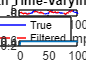

% 11/11/2024
% Time-Varying Kalman Filter Design
% first, generate the noisy plant response.
yt = lsim(sys, [u w]);
y = yt + v;

% Next, implement the recursive filter update equations in a for loop.
P = B * Q * B';      % Initial error covariance
x = zeros (3, 1); % Initial condition on the state

ye = zeros (length(t), 1);
ycov = zeros (length(t), 1);
errcov = zeros (length(t),1);

for i = 1 : length(t)
    % Measurement update
    Mxn = P * C' / (C * P * C' + R) ;
    x = x + Mxn* (y(i) - C * x);    % x[n|n]
    P = (eye(3) - Mxn * C) * P;     % P[n|n]
    ye(i) = C * x;
    errcov(i) = C * P * C';

    % Time update
    x = A * x + B * u(i);          % x[n+1|n]
    P = A * P * A' + B * Q * B';   % P[n+1|n]
end

% Compare the true response with the filtered response.
subplot(211), plot(t, yt, 'b', t, ye, 'r--')
xlabel('Number of Samples'), ylabel('Output')
title('Response with Time-Varying Kalman Filter')
legend ('True', 'Filtered')
subplot(212), plot(t, yt-y, 'g', t, yt - ye, 'r--'),
xlabel('Number of Samples'), ylabel('Error')
legend( 'True - measured', 'True - filtered')

% Plot the output covariance to confirm that the filter has reached a steady state. figure
plot(t, errcov)
xlabel('Number of Samples'), ylabel('Error Covariance')



MeasErr = yt - y;
MeasErrCov = sum(MeasErr .* MeasErr) / length(MeasErr);
MeasErrCov

MeasErrCov = 0.9871


EstErr = yt - ye;
EstErrCov = sum(EstErr .* EstErr)/length(EstErr);
EstErrCov

EstErrCov = 0.3479



Mx, Mxn % 和 上個程式 kalman_filter0 比較

Mx =     0.5345
    0.0101
   -0.4776


Mxn =     0.5345
    0.0101
   -0.4776
